## **Przetwarzanie Sygnałów Cyfrowych**

# **Parametry sygnalow cyfrowych**

## Jan Rosa 410269 AiR

### Zad 1

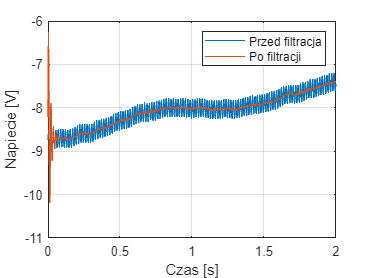

% wczytywanie pliku
figure
load openloop60hertz, openLoop=openLoopVoltage;
Fs=1000;
t=(0:length(openLoop)-1)/Fs;
plot(t, openLoop); box on; grid on;
ylabel 'Voltage [V]', xlabel 'Time [s]'
title 'Open-Loop Voltage with Noise'
%% Power spectrum - Moc
%% na ok 60 Hz widzimy 
figure;
periodogram(openLoop, [], [], Fs);
%% Projektujemy filtr
filtCoeff= designfilt('bandstopiir', 'FilterOrder', 2,...
'HalfPowerFrequency1', 50, 'HalfPowerFrequency2', 70, ...
'SampleRate', Fs);
%% Wykres filtru
%fvtool(filtCoeff)
noiseFreeSignal= filter(filtCoeff, openLoop);
%% sprawadzamy wynik w dziedzinie czasu
close all;
figure;
plot (t, openLoop, t, noiseFreeSignal); grid on;
legend('Przed filtracja', 'Po filtracji');
ylabel 'Napiecie [V]', xlabel 'Czas [s]'

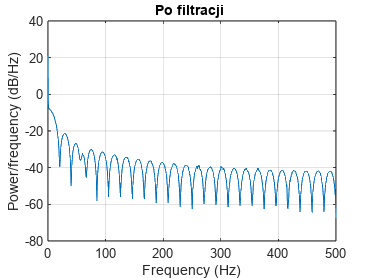

%% sprawdzamy wynik w dziedzinie częstotliwości
figure;
periodogram(noiseFreeSignal, [], [], Fs);
title('Po filtracji ');

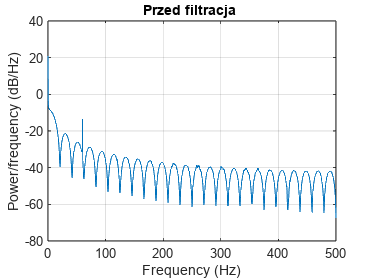

figure;
periodogram(openLoop, [], [], Fs);
title('Przed filtracja ');
hold off;

### Zad 2

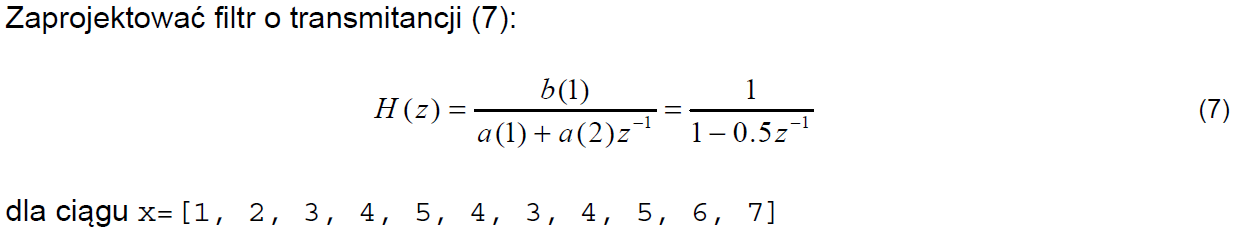

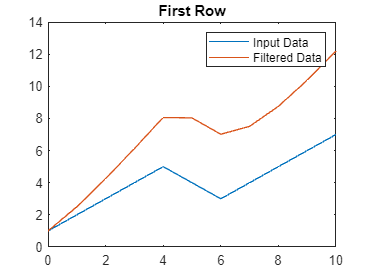

figure
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = 1;
a = [1 -0.5];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data')
title('First Row')

### Zad 3

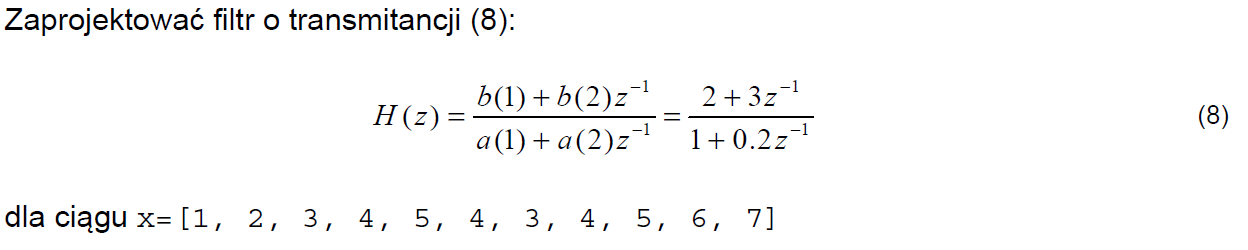

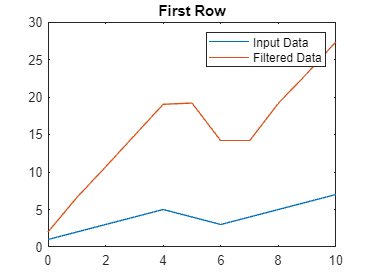

figure
x = [1, 2, 3, 4, 5, 4, 3, 4, 5, 6, 7];
b = [2 3];
a = [1 0.2];
y = filter(b,a,x,[],2);
t = 0:length(x)-1; %indeks wektora
plot(t,x(1,:))
hold on
plot(t,y(1,:))
legend('Input Data','Filtered Data')
title('First Row')

### Zad 4

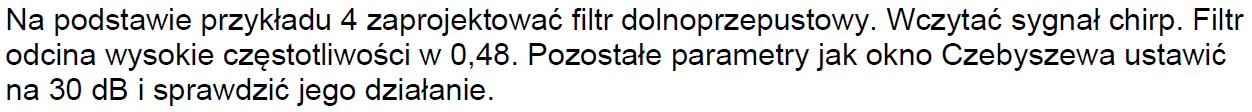

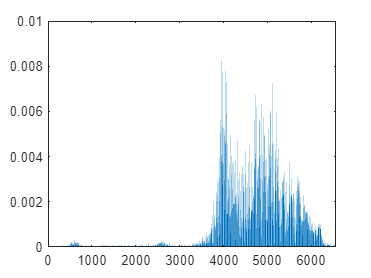

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

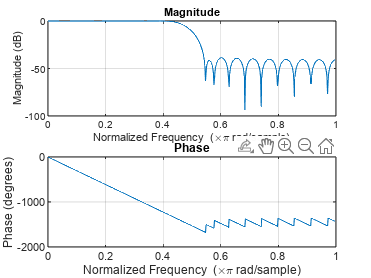

bhi = fir1(34,0.48,'low',chebwin(35,30));
freqz(bhi,1)

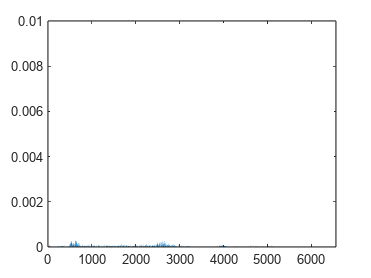

fvtool(bhi)
outhi = filter(bhi,1,y);
xfft=abs(fft(outhi));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

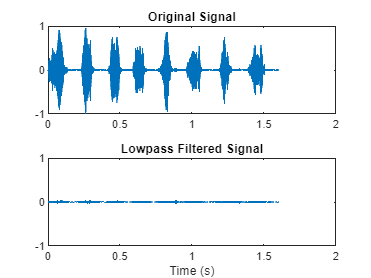

subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;
subplot(2,1,2)
plot(t,outhi)
title('Lowpass Filtered Signal')
xlabel('Time (s)')
ylim(ys)

### Zad 5

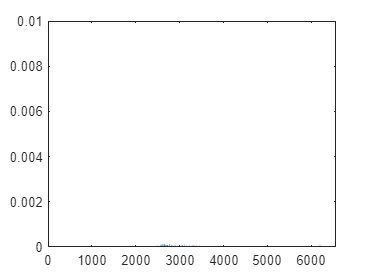

load chirp
figure
t = (0:length(y)-1)/Fs; % 1.6 sekundy
ord = 46;
low = 0.4;
bnd = [0.5 0.99];
bM = fir1(ord,[low bnd], 'DC-1');
bW = fir1(ord,[low bnd]);
%figure(fvtool(bM, 1, bW, 1));
outF = filter(bW,1,y);
xfft=abs(fft(outF));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]);
hold off;

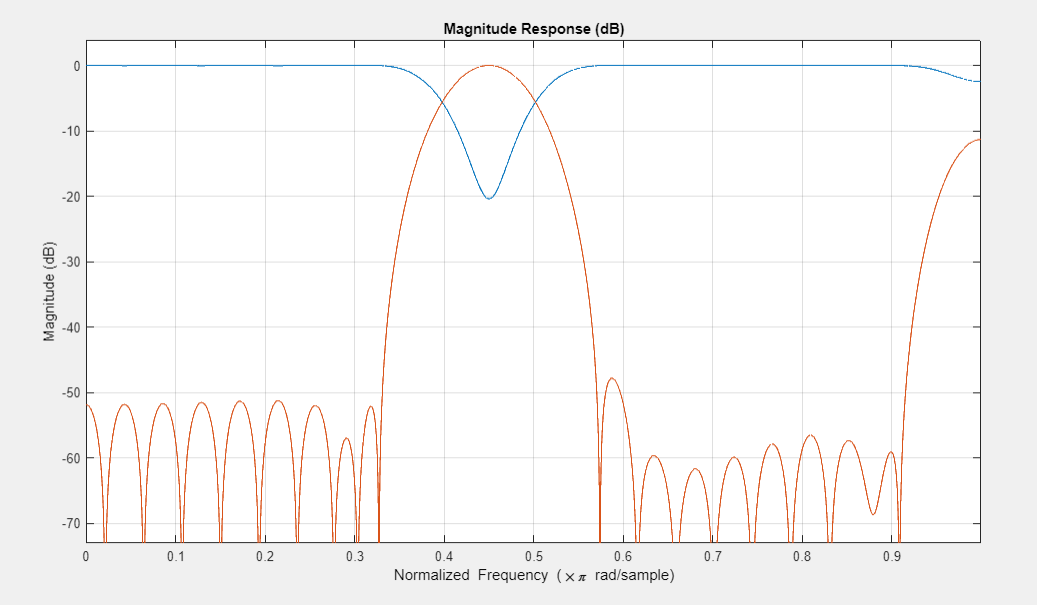

### Zad 6

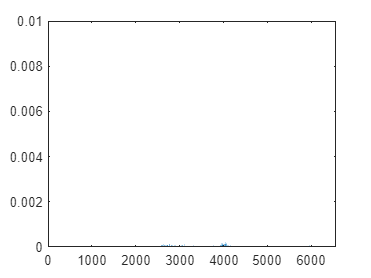

load chirp
figure
t = (0:length(y)-1)/Fs; % 1.6 sekundy
tM = fir1(ord,[low bnd],'DC-0',tukeywin(ord+1));
bM = fir1(ord,[low bnd],'DC-0',hamming(ord+1));
hfvt = fvtool(bM,1,tM,1); %porownanie okien
legend(hfvt,'Hamming','Tukey')
outhann = filter(tM,1,y);
xfft=abs(fft(outhann));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

hold off;

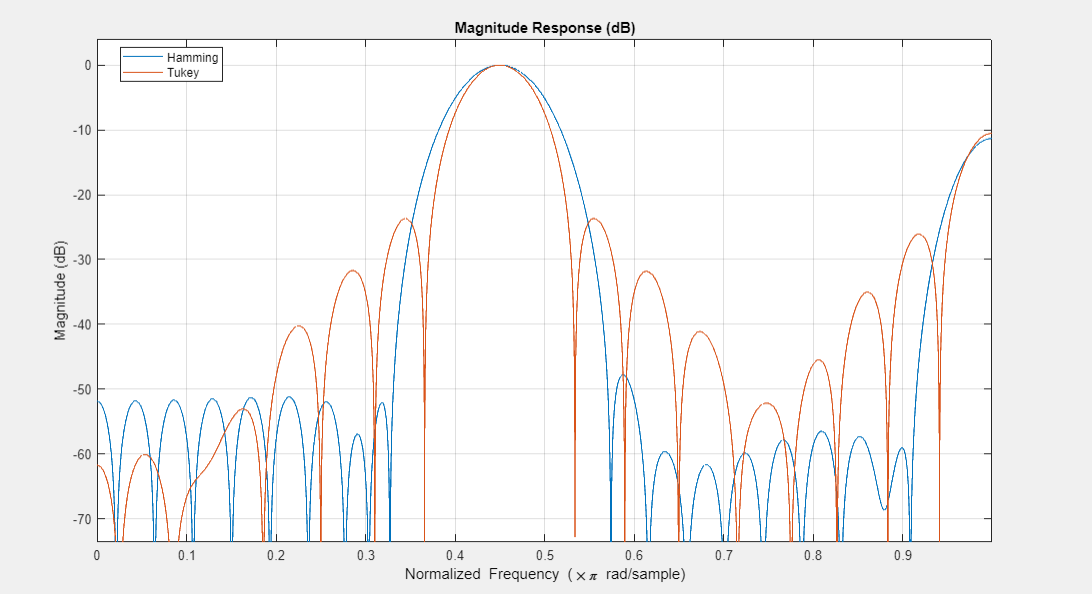

### Zad 7

files = ["wiatrak_20.wav"; "wiatrak_21.wav"; 'wiatrak_23.wav'; 'wiatrak_24.wav'; 'przekladnia20.wav'; 'przekladnia21.wav'; 'przekladnia23.wav'; 'przekladnia24.wav'];
texts = ["FFT_filtracja_wiatrak20.txt"; 'FFT_filtracja_wiatrak21.txt'; 'FFT_filtracja_wiatrak23.txt'; 'FFT_filtracja_wiatrak24.txt'; 'FFT_filtracja_przekladnia20.txt'; 'FFT_filtracja_przekladnia21.txt'; 'FFT_filtracja_przekladnia23.txt'; 'FFT_filtracja_przekladnia24.txt'];
for i = 1:size(files)
    [data, fz] = audioread(files(i));
    x2=data;
    % normalizacja do przedzialu [-1, 1] jesli sygnaly sa mierzone wroznych odleglosciach
    max_data=max(abs(data));
    data=data/max_data;
    xfft=abs(fft(x2));
    xfft=xfft/44100;
    xfft(500:1000)=0;
    %zapisywanie do pliku FFT_filtracja_wiatrak20.txt
    fid = fopen(texts(i),'w+t','n');
    fprintf(fid,'%f\n',xfft(1:22050));
    fclose(fid);
end

figure
load FFT_filtracja_wiatrak20.txt
load FFT_filtracja_wiatrak21.txt
load FFT_filtracja_przekladnia20.txt
load FFT_filtracja_przekladnia21.txt
load FFT_filtracja_wiatrak23.txt
load FFT_filtracja_wiatrak24.txt
load FFT_filtracja_przekladnia23.txt
load FFT_filtracja_przekladnia24.txt
D = [];
D(1)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak20))

D = 5.2142

D(2)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak21))

D =     5.2142    5.1181


D(3)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia20))

D =     5.2142    5.1181    5.7600


D(4)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia21))

D =     5.2142    5.1181    5.7600    5.7562


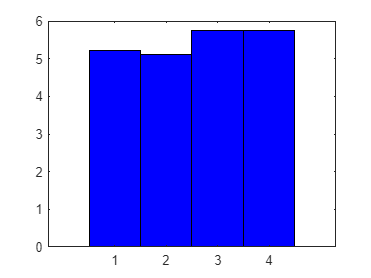

bar(1:4, D, 1, "stacked", 'blue');

D(1)=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_wiatrak20))

D =     5.4104    5.1181    5.7600    5.7562


D(2)=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_wiatrak21))

D =     5.4104    5.2007    5.7600    5.7562


D(3)=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_przekladnia20))

D =     5.4104    5.2007    5.9176    5.7562


D(4)=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_przekladnia21))

D =     5.4104    5.2007    5.9176    5.9181


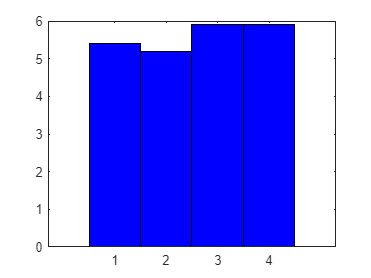

bar(1:4, D, 1, "stacked", 'blue');

D(1)=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_wiatrak20))

D =     6.0185    5.2007    5.9176    5.9181


D(2)=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_wiatrak21))

D =     6.0185    5.9986    5.9176    5.9181


D(3)=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_przekladnia20))

D =     6.0185    5.9986    4.8491    5.9181


D(4)=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_przekladnia21))

D =     6.0185    5.9986    4.8491    4.6975


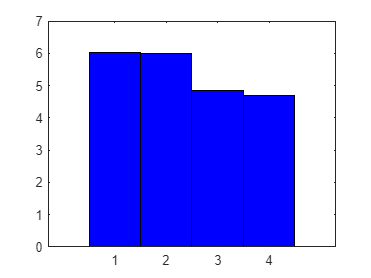

bar(1:4, D, 1, "stacked", 'blue');

D(1)=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_wiatrak20))

D =     6.0199    5.9986    4.8491    4.6975


D(2)=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_wiatrak21))

D =     6.0199    5.8897    4.8491    4.6975


D(3)=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_przekladnia20))

D =     6.0199    5.8897    4.7168    4.6975


D(4)=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_przekladnia21))

D =     6.0199    5.8897    4.7168    4.9471


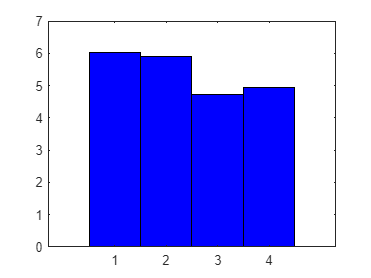

bar(1:4, D, 1, "stacked", 'blue');

D(1)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak20))

D =     5.2142    5.8897    4.7168    4.9471


D(2)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak21))

D =     5.2142    5.1181    4.7168    4.9471


D(3)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia20))

D =     5.2142    5.1181    5.7600    4.9471


D(4)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia21))

D =     5.2142    5.1181    5.7600    5.7562


bar(1:4, D, 1, "stacked", 'blue');

### Zad 8

files = ["wiatrak_20.wav"; "wiatrak_21.wav"; 'wiatrak_23.wav'; 'wiatrak_24.wav'; 'przekladnia20.wav'; 'przekladnia21.wav'; 'przekladnia23.wav'; 'przekladnia24.wav'];
texts = ["FFT_filtracja_wiatrak20.txt"; 'FFT_filtracja_wiatrak21.txt'; 'FFT_filtracja_wiatrak23.txt'; 'FFT_filtracja_wiatrak24.txt'; 'FFT_filtracja_przekladnia20.txt'; 'FFT_filtracja_przekladnia21.txt'; 'FFT_filtracja_przekladnia23.txt'; 'FFT_filtracja_przekladnia24.txt'];
for i = 1:size(files)
    [data, fz] = audioread(files(i));
    x2=data;
    % normalizacja do przedzialu [-1, 1] jesli sygnaly sa mierzone wroznych odleglosciach
    max_data=max(abs(data));
    data=data/max_data;
    xfft=abs(fft(x2));
    xfft=xfft/44100;
    xfft(100:1500)=0;
    %zapisywanie do pliku FFT_filtracja_wiatrak20.txt
    fid = fopen(texts(i),'w+t','n');
    fprintf(fid,'%f\n',xfft(1:22050));
    fclose(fid);
end

figure
load FFT_filtracja_wiatrak20.txt
load FFT_filtracja_wiatrak21.txt
load FFT_filtracja_przekladnia20.txt
load FFT_filtracja_przekladnia21.txt
load FFT_filtracja_wiatrak23.txt
load FFT_filtracja_wiatrak24.txt
load FFT_filtracja_przekladnia23.txt
load FFT_filtracja_przekladnia24.txt
D = [];
D(1)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak20))

D = 4.3953

D(2)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak21))

D =     4.3953    4.3155


D(3)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia20))

D =     4.3953    4.3155    4.8245


D(4)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia21))

D =     4.3953    4.3155    4.8245    4.8174


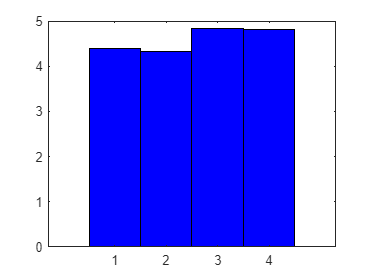

bar(1:4, D, 1, "stacked", 'blue');

D(1)=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_wiatrak20))

D =     4.4679    4.3155    4.8245    4.8174


D(2)=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_wiatrak21))

D =     4.4679    4.4271    4.8245    4.8174


D(3)=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_przekladnia20))

D =     4.4679    4.4271    4.9652    4.8174


D(4)=sum(abs(FFT_filtracja_wiatrak24-FFT_filtracja_przekladnia21))

D =     4.4679    4.4271    4.9652    4.9698


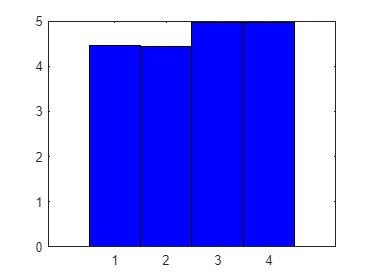

bar(1:4, D, 1, "stacked", 'blue');

D(1)=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_wiatrak20))

D =     5.0328    4.4271    4.9652    4.9698


D(2)=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_wiatrak21))

D =     5.0328    5.0457    4.9652    4.9698


D(3)=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_przekladnia20))

D =     5.0328    5.0457    4.4282    4.9698


D(4)=sum(abs(FFT_filtracja_przekladnia23-FFT_filtracja_przekladnia21))

D =     5.0328    5.0457    4.4282    4.3161


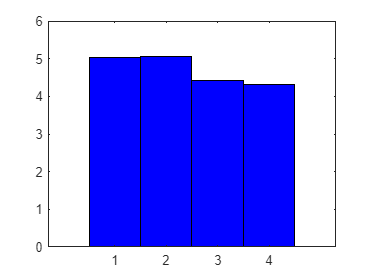

bar(1:4, D, 1, "stacked", 'blue');

D(1)=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_wiatrak20))

D =     5.0295    5.0457    4.4282    4.3161


D(2)=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_wiatrak21))

D =     5.0295    4.9216    4.4282    4.3161


D(3)=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_przekladnia20))

D =     5.0295    4.9216    4.3146    4.3161


D(4)=sum(abs(FFT_filtracja_przekladnia24-FFT_filtracja_przekladnia21))

D =     5.0295    4.9216    4.3146    4.5397


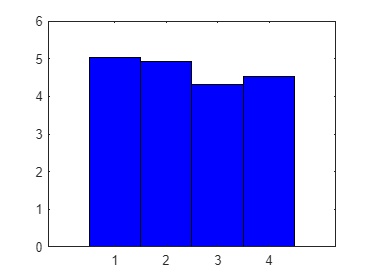

bar(1:4, D, 1, "stacked", 'blue');

D(1)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak20))

D =     4.3953    4.9216    4.3146    4.5397


D(2)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_wiatrak21))

D =     4.3953    4.3155    4.3146    4.5397


D(3)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia20))

D =     4.3953    4.3155    4.8245    4.5397


D(4)=sum(abs(FFT_filtracja_wiatrak23-FFT_filtracja_przekladnia21))

D =     4.3953    4.3155    4.8245    4.8174


bar(1:4, D, 1, "stacked", 'blue');

### Pytania Kontrolne

1) Filtracja jest procesem przetwarzania syganłów. Polega na redukowaniu nieporządanych składowych zawartych w sygnale, np szumów i zakłóceń.

2) Jest to filtr cyfrowy. Mnożąc przez stałe i dodając skończoną ilość przeszłych próbek sygnału wejściowego generuje sygnał wyjściowy.

3) Projektowanie ww filtry FIR jest projektowany w takiu sposób aby wartość sygnału wejściowego była pożądany dyskretnym splotem dającym odpowiednie wyniki.

4) Okna służą do zmniejszania zafalowań charakterystyk powstałych z FFT/DFT.